# Poses From Merged Point Clouds: A Strategy

Why merge point clouds??

It will allow us to get more accurate pose estimates.

## Getting Add-Ons

Please make sure you have the following toolboxes installed before you proceed:

- [**Computer Vision Toolbox** ](https://www.mathworks.com/add-ons/VP/?s_tid=srchtitle)

- [**Statistics and Machine Learning Toolbox**](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'ST', 'focused', 'pca');)**.**

## Getting the Files

There will be two steps to download necessary files: (1) Regular files via GIT as usual and (2) Large Neural Net Yolo file downloaded from the internet.

### (1) GIT Files

Fetch and Merge the latest files from GIT.

You should see a folder structure as the one below. Make **vision_tutorials **the top folder in your matlab path:

**vision_tutorials  <-- make this top folder in path**

  |__ pt_clouds

          |__ detectors

          |__ helper_files

          |__ 09_perception_basics.mlx

          |__ 10_accessing_imgs_ptClouds.mlx

### (2) Detector Files

Download directly from this --> [**link**](https://lipscomb.instructure.com/users/55882/files/4803628/download?download_frd=1) <-- and place the detector file in the **ros_matlab/vision_tutorials/detectors **folder. 

File size ~230MB.

### *Add to Matlab Path

Note that vision_tutorials is a new folder with sub-folders inside of it. 

Please add it to your Matlab path.

### Read sample point cloud and sample RGB data 

From the top of the vision_tutorials folder, load data to use with this example notebook. It will load:

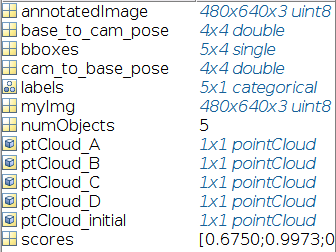

load("./pt_clouds/helper_files/example_poses_from_merged_ptClouds.mat");

## Merging Point Clouds (with the intent to get a pose from merged)

FLOWCHART!

### Collect and Label Image

Move to where you want to take your picture to identify objects.

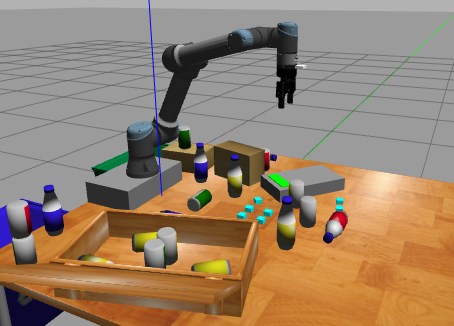

Take a picture and apply the trained YOLO network to it. The output of this step will include:

- `bboxes:` P-by-4 array defining P bounding boxes. Each row of `bboxes` contains a four-element vector, [x, y, width, height]. This vector specifies the upper-left corner and size of a bounding box in pixels. 

- `scores:` confidence scores for each bounding box (P-by-1)

- `labels:` labels assigned to the bounding boxes (P-by-1)

- `numObjects:` number of objects detected ( would also be P )

- `myImg:` image taken without any labels

- `annotatedImage: myImg` but with bounding boxes, scores, and labels for each object detected

Display the raw RGB image the robot took.

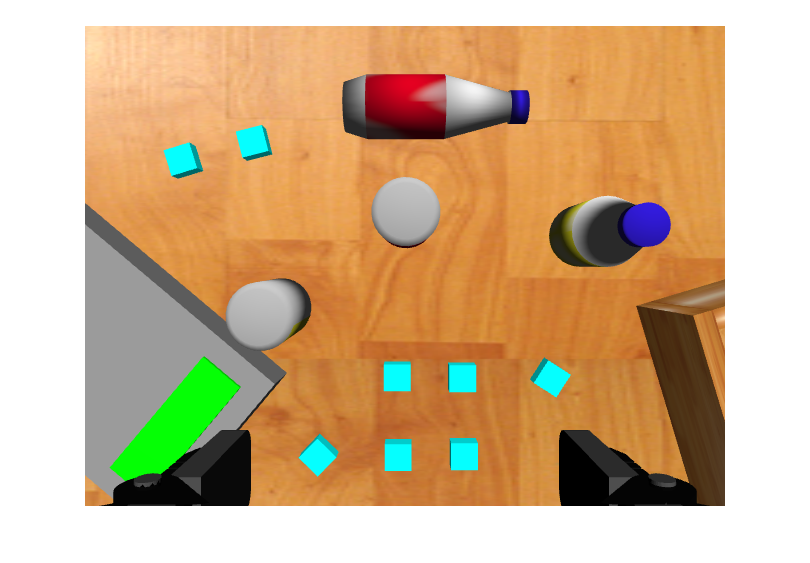

figure, imshow(myImg)

Observe the outputs of the trained network when applied to the raw image.

bboxes

bboxes = 5×4 single matrix
   76.5599  115.5324   45.5922   38.8953
  142.7141  253.2398   87.0278   77.2787
  288.7034  151.4417   66.7700   74.1230
  465.3229  155.6052  123.1520  103.3628
  234.3463   34.5581  244.5389   84.4704


scores

scores = 5×1 single column vector
    0.6750
    0.9973
    0.9898
    0.9992
    0.9999


labels

labels = 5×1 categorical array
     pouch 
     can 
     can 
     bottle 
     bottle 


numObjects

numObjects = 5

Display the annotated image where the information from the detector was applied.

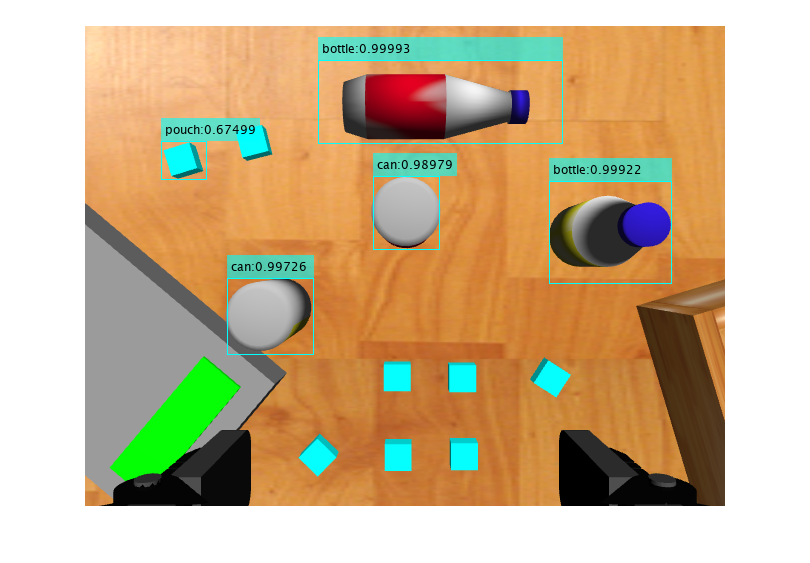

figure, imshow(annotatedImage)

### Collect Point Clouds

At the position where the raw image was taken, a point cloud also needs to be taken. Let's call this `ptCloud_initial.` Run the next line and see how the point cloud object holds x-, y-, and z-limits. 

ptCloud_initial

ptCloud_initial =   pointCloud with properties:

     Location: [293520×3 single]
        Count: 293520
      XLimits: [0.4720 1.0229]
      YLimits: [-0.3335 0.4014]
      ZLimits: [-0.1004 0.0973]
        Color: []
       Normal: []
    Intensity: []


**Crop intial point cloud**

Depending on where you are taking a picture and/or point coud on the table, sometimes the floor or bins could be picked up by the depth sensors. Having these in the point cloud will scew the xyz limits and other things when we are doing some later calculations. 

The process to "crop" this point cloud to eliminate the z-points we don't want includes creating an ROI (region of interest). The z limits were picked so that only elements on the table would be included in the point cloud.

% Gather the x and y limits of this first point cloud and store them
xlim_min = ptCloud_initial.XLimits(1,1);
xlim_max = ptCloud_initial.XLimits(1,2);
ylim_min = ptCloud_initial.YLimits(1,1);
ylim_max = ptCloud_initial.YLimits(1,2);
zlim_min = -0.13; zlim_max = 0.4; % zlim_min is the bottom of the table
roi = [xlim_min xlim_max ylim_min ylim_max zlim_min zlim_max]; 

% crop z values
indices = findPointsInROI(ptCloud_initial,roi);
ptCloud_initial = select(ptCloud_initial,indices);

Visualize the point cloud

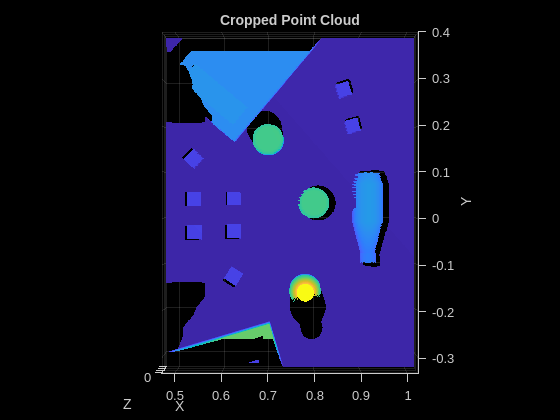

figure, pcshow(ptCloud_initial,'ViewPlane','XY'); axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("Cropped Point Cloud");

Now that `ptCloud_inital` is cropped to make sure it only includes items on the table and nothing below, we can update our xyz-limits of the point cloud.

% update xyz limits
xlim_min = ptCloud_initial.XLimits(1,1);
xlim_max = ptCloud_initial.XLimits(1,2);
ylim_min = ptCloud_initial.YLimits(1,1);
ylim_max = ptCloud_initial.YLimits(1,2);
zlim_min = -0.13; zlim_max = 0.4;

Now create a new ROI that holds the xyz limits of the cropped point cloud. This point cloud now has the same xy-limits of the raw image that we collected. We want to keep track of this area, so we store this ROI in `pic_roi`.

pic_roi = [xlim_min xlim_max ylim_min ylim_max zlim_min zlim_max];

Now create an ROI that is for the xyz of the entire table.

table_roi = [-0.3 2 -1.5 1.5 zlim_min zlim_max];

**Get additional point clouds**

Now we can move the robot to a different position and take a point cloud. This position can be angled however you want and does not have to be square to the table or XY-plane. You also don't need to collect another image for theis position, only a point cloud.

`myImg` and `ptCloud_initial` will be what we are focusing on. We will collect additional point clouds and merge them into `ptCloud_inital` so that we can collect more points to have a better 3D representation of the objects within `myImg`.

Here is the position in which ptCloud_A was taken.

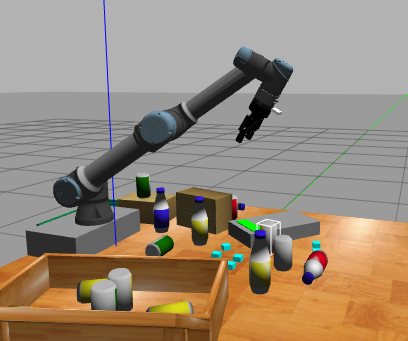

Display ptCloud_A

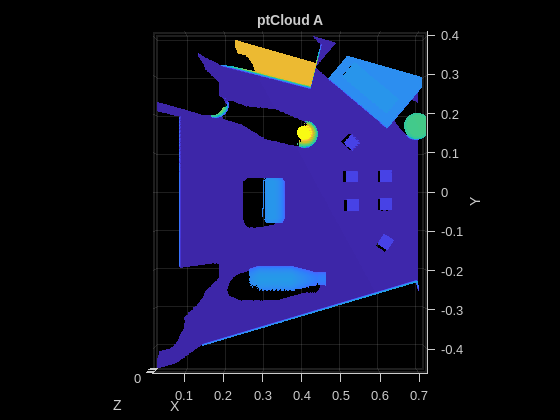

figure, pcshow(ptCloud_A,'ViewPlane','XY'); axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("ptCloud A");

Here is the position in which ptCloud_B was taken.

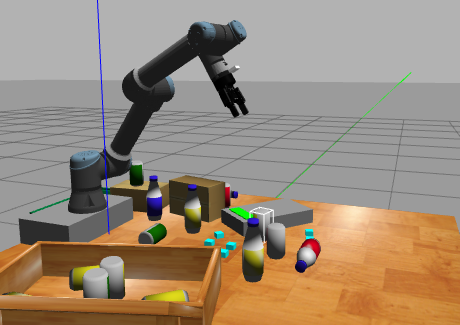

Display ptCloud_B

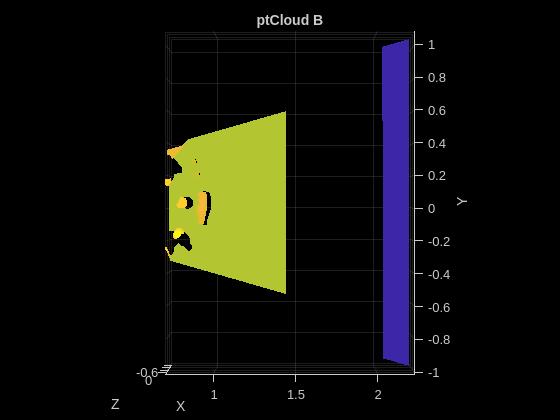

figure, pcshow(ptCloud_B,'ViewPlane','XY'); axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("ptCloud B");

Here is the position in which ptCloud_C was taken.

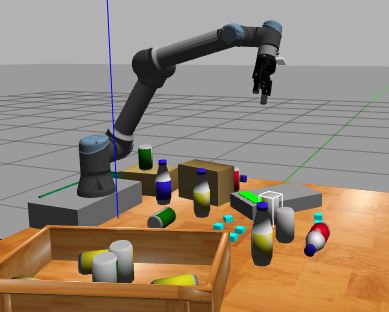

Display ptCloud_C

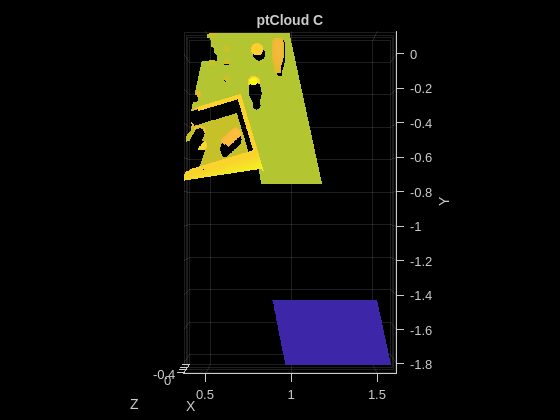

figure, pcshow(ptCloud_C,'ViewPlane','XY'); axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("ptCloud C");

Here is the position in which ptCloud_D was taken.

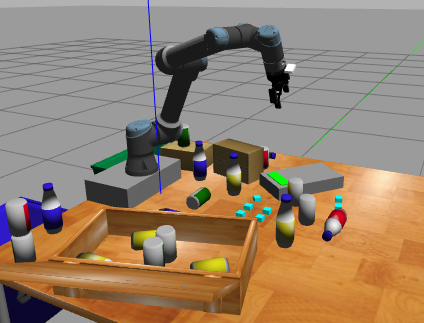

Display ptCloud_D

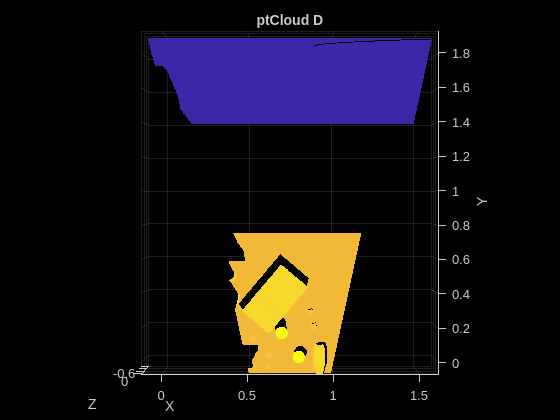

figure, pcshow(ptCloud_D,'ViewPlane','XY'); axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("ptCloud D");

### Merge Point Clouds

The function for merging point clouds is `pcmerge`.

`pcmerge`: merge two 3D point clouds together. This function returns a merged point cloud using a box grid filter in the region of overlap (downsamples to the gripStep input)

    Syntax

        `ptCloudOut = ``pcmerge``(ptCloudA, ptCloudB, gridStep)`

Because `pcmerge` can only merge two point clouds at a time, let's create `ptCloud_world` to hold our merged point cloud.

Merge `ptCloud_inital` and `ptCloud_A`

ptCloud_world = pcmerge(ptCloud_initial, ptCloud_A, 0.001);

Display the result. Notice how the it has the points from both point clouds and is larger.

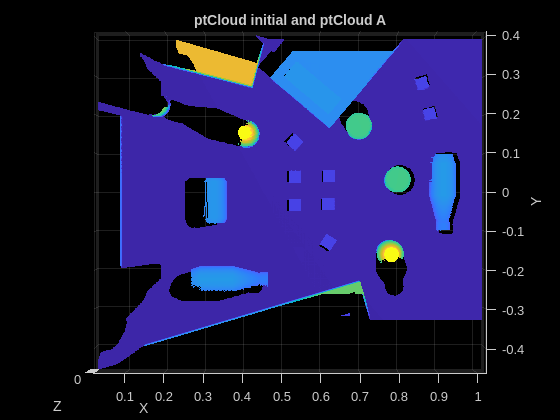

figure, pcshow(ptCloud_world,'ViewPlane','XY'); axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("ptCloud initial and ptCloud A");

Now merge the other three point clouds with `ptCloud_world` as well.

% merge ptCloud intial, A, and B
ptCloud_world = pcmerge(ptCloud_world, ptCloud_B, 0.001);
% merge ptCloud intial, A, B, and C
ptCloud_world = pcmerge(ptCloud_world, ptCloud_C, 0.001);
% merge all point clouds together
ptCloud_world = pcmerge(ptCloud_world, ptCloud_D, 0.001);

`ptCloud_world` is now all of the point clouds merged together!

Display the result. Notice how it looks really odd. That is because it is catching some of the floor.

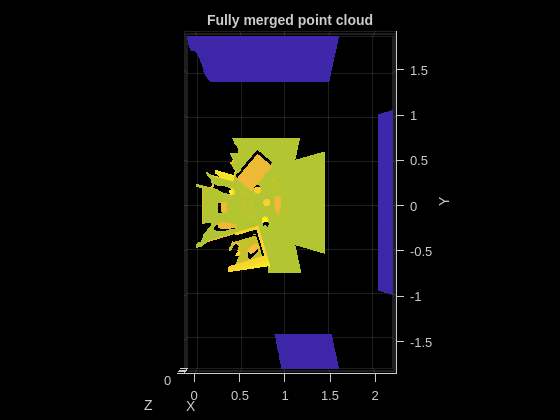

figure, pcshow(ptCloud_world,'ViewPlane','XY'); axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("Fully merged point cloud");

Crop ptCloud_world so that it is only the table and above.

% use table_roi created earlier
indices = findPointsInROI(ptCloud_world,table_roi);
ptCloud_world = select(ptCloud_world,indices);

Visualize. Notice it is much easier to see the items now.

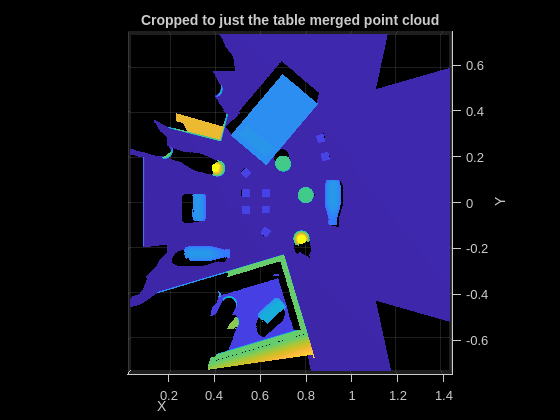

figure, pcshow(ptCloud_world,'ViewPlane','XY'); axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("Cropped to just the table merged point cloud");

Now we are going to take just the points within the field of view of `myImg` and store that in `ptCloud_pic`.

indices = findPointsInROI(ptCloud_world,pic_roi); 
ptCloud_pic = select(ptCloud_world,indices);

### Separate the Plane and the Objects

planeThickness = .001;
normalVector = [0,0,1];
maxPlaneTilt = 5;
[param, planeIdx, nonPlaneIdx] = pcfitplane(ptCloud_pic, planeThickness, normalVector, maxPlaneTilt);
plane_pic = select(ptCloud_pic, planeIdx);
nonPlane_pic = select(ptCloud_pic, nonPlaneIdx);

You can see how this split the point cloud into just the table (`plane_pic`) and then just the objects (`nonPlane_pic`).

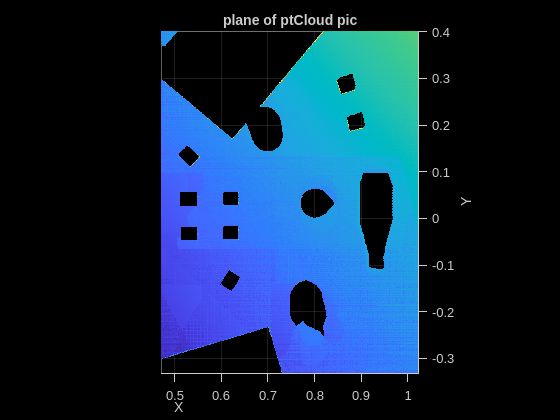

 % show plane
figure,pcshow(plane_pic,'ViewPlane','XY');axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("plane of ptCloud pic");

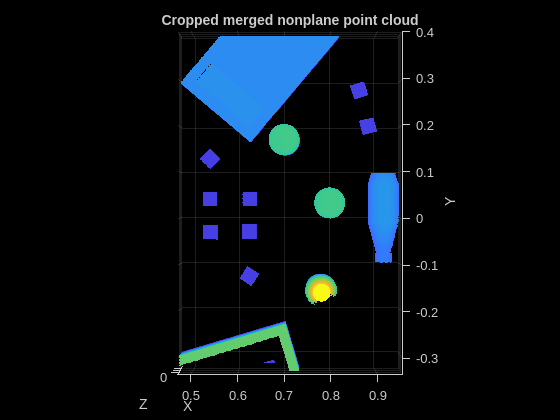

% show items
figure,pcshow(nonPlane_pic,'ViewPlane','XY');axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("Cropped merged nonplane point cloud");

The result is not perfect 3D modeling of the objects, but it is much better than `ptCloud_initial`. Taking more point clouds at different angles can help make it better but we will work with this for now.

## Get Poses

For visualization it is easiest to keep the point clouds in reference to the `base_link`. However, for getting the pose, we will need to transform our point cloud `ptCloud_pic` to be with respect to the `camera_depth_link`.

`base_to_cam_pose` is the 4x4 transformation of the arm from **the **`base_link`** to the **`camera_depth_link` at the position `myImg` and `ptCloud_initial` were taken.

`cam_to_base_pose` is the 4x4 transformation of the arm from the `camera_depth_link`** to the **`base_link` at the position `myImg` and `ptCloud_initial` were taken.

The function for transforming point clouds is `pctransform`.

`pctransform`: transform 3D point cloud. This function applies the specified transform, `tform`, to the point cloud, `ptCloudIn`.

    Syntax

        `ptCloudOut = ``pctransform``(ptCloudIn,tform)`

`tform` does have to be a `rigidtform3d` object!

Transform `ptCloud_pic and nonPlane_pic` to the `camera_depth_link` refernce frame by using `cam_to_base_pose`.

to_cam_tform = rigidtform3d(cam_to_base_pose);
ptCloud_tform_cam = pctransform(ptCloud_pic, to_cam_tform);
nonPlane_tform_cam = pctransform(nonPlane_pic, to_cam_tform);

Display the results to see how a point cloud with respect to `camera_depth_link` is different from being with respect to `base_link`.

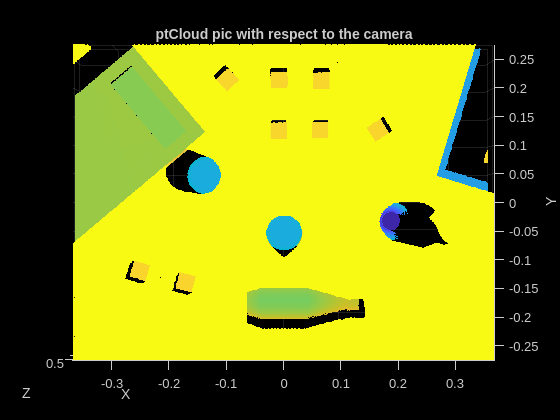

figure, pcshow(ptCloud_tform_cam,'ViewPlane','XY'); axis on;
xlabel("X"); ylabel("Y"); zlabel("Z"); title("ptCloud pic with respect to the camera");

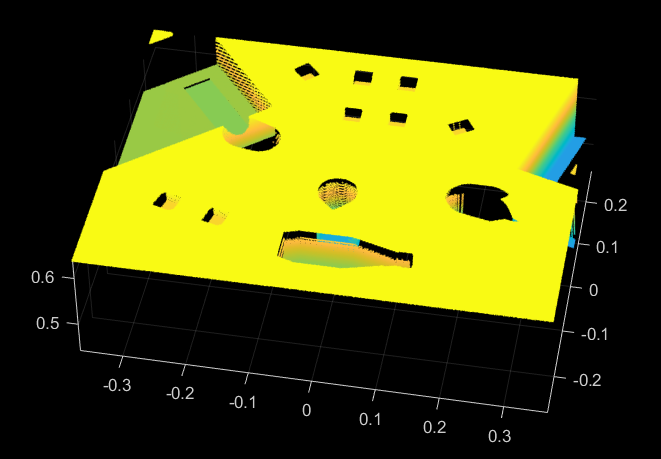

Notice how it is the same but upside down. Points clouds with respect to camera_depth_link are always upside down. Also notice that the numbers on the axises are different from previously. (0,0) is now in the very center of the point cloud.

### BetterObjectPoses: A Walkthrough

The bounding box sizes and location are given in reference to the size of the raw RGB image It is basically given in units of pixels where (0,0) is the top left corner of the image. 

In order to identify the objects from the point cloud, the bounding boxes need to be essentially layed over the point cloud and find the bounding boxes with respect to the point cloud frame. To do this we need to find the scale of a pixel compared to the point cloud. 

Below is a transparent version of an annotated image layed over a point cloud with respect to base_link as an example to show essentially what we are conceptually doing through steps in the code.

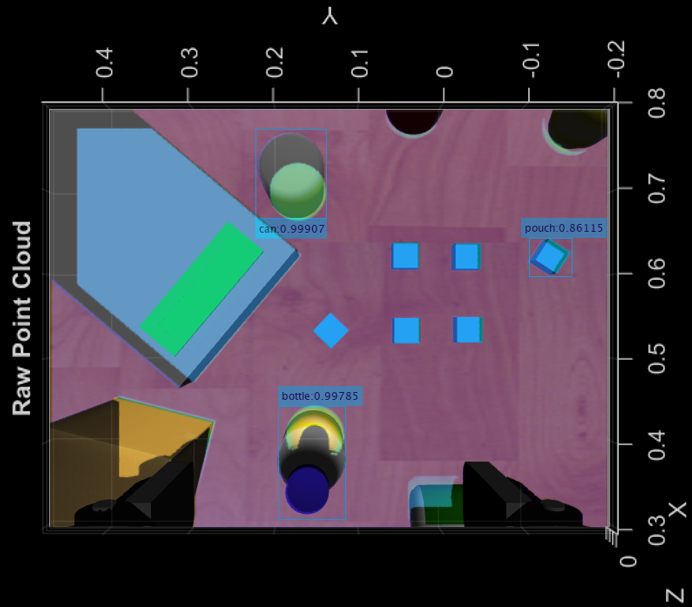

First, declare and allocate some variables

% declaring and allocating variables
numObjects = size(bboxes,1);
ptCloud_vec = cell(numObjects, 1);
scene_pca_vec = cell(numObjects, 1);
theta = [];
xyz =[];

We want to find the XYZ-limits of the point cloud we are examining, `ptCloud_tform_cam,` the transformed cropped point cloud with respect to the camera`.`

% finding the xyz limits of the point cloud
pc_xmin = ptCloud_tform_cam.XLimits(1); % pc stands for point cloud
pc_xmax = ptCloud_tform_cam.XLimits(2);

pc_ymin = ptCloud_tform_cam.YLimits(1);
pc_ymax = ptCloud_tform_cam.YLimits(2);

pc_zmin = ptCloud_tform_cam.ZLimits(1);
pc_zmax = ptCloud_tform_cam.ZLimits(2);

We also want the dimensions of the image.

[m,n,~] = size(myImg); % get the size of image

Remember, this is our image and its conventions.

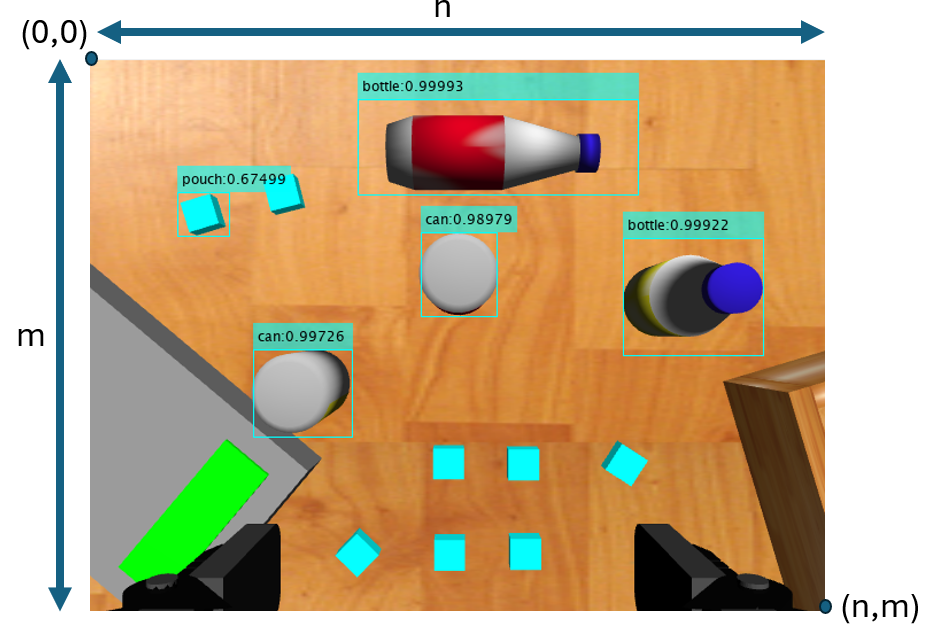

If we visualize our point cloud and rotate it to match the orientation of the image, we can see how `n` and `m` correlate with the `x` and `y` min and `max`.

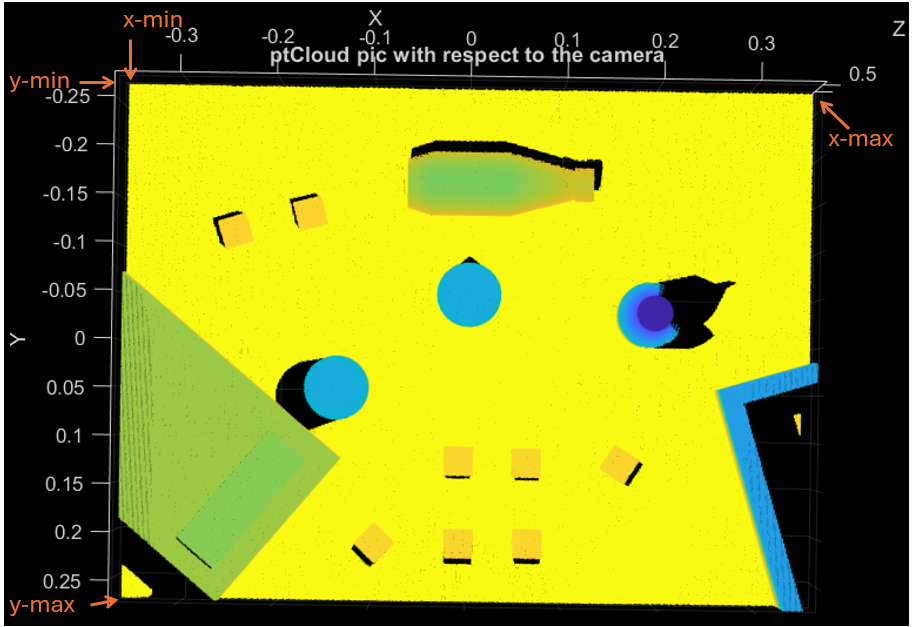

Calculate the pixel scale for the x and y directions.

% calculate the pixel scale for width and height
xpixel_base_scale = (pc_xmax - pc_xmin)/n;
ypixel_base_scale = (pc_ymax - pc_ymin)/m;

### Start of for loop

This next part would all be in a for loop that would iterate through each detected object.

For good measure to ensure the bounding boxes include the entire point cloud object, let's increase their size by 30%.

Remember how bboxes variable is set up.

- `bboxes:` P-by-4 array defining P bounding boxes. Each row of `bboxes` contains a four-element vector, [x, y, width, height]. This vector specifies the upper-left corner and size of a bounding box in pixels. 

bboxes

bboxes = 5×4 single matrix
   76.5599  115.5324   45.5922   38.8953
  142.7141  253.2398   87.0278   77.2787
  288.7034  151.4417   66.7700   74.1230
  465.3229  155.6052  123.1520  103.3628
  234.3463   34.5581  244.5389   84.4704


In order to increase the size of the boxes, 15% of the size will be added on each side of the bouding box. Calculate the 1/6 of width and the height of the bounding box for the object.

%for idx = 1:numObjects
    idx = 1;
    % get the bouding box edges with respect to the image size/pixels
    xincrease = bboxes(idx,3)/6;
    yincrease = bboxes(idx,4)/6;

Now find the new pixel locations for the edges of the bounding box in terms of pixels. Below is a diagram of an example to help understand what the code is doing.

    % find the columns and rows of the pixel image the bounding box edges are on
    left_column = bboxes(idx,1) - xincrease;
    right_column = bboxes(idx,1) + bboxes(idx,3) + xincrease;

    top_row = bboxes(idx,2) - yincrease;
    bottom_row = bboxes(idx,2) + bboxes(idx,4) + yincrease;

    % these are conditionals for if the bounding box edges are calculated to be outside 
    % the mxn image to make them the max/min of the image
    if left_column < 1
        left_column = 1;
    end
    if right_column > n
        right_column = n;
    end
    if top_row < 1
        top_row = 1;
    end
    if bottom_row > m
        bottom_row = m;
    end

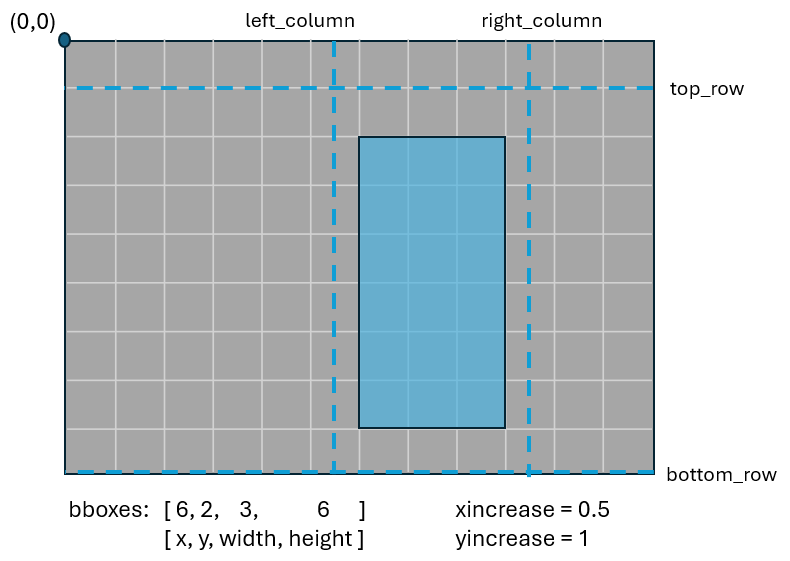

Now that we know where the edges of the bounding box are on the image, we can calculate the point cloud x and y locations of the bounding box by using the scale we calculated earlier. 

    % use bounding box locations on the image and translate them to the
    % camera_depth_link reference
    bbox_roi_xmin = pc_xmin + (left_column*xpixel_base_scale);
    bbox_roi_xmax = pc_xmin + (right_column*xpixel_base_scale);

    bbox_roi_ymin = pc_ymin + (top_row*ypixel_base_scale);
    bbox_roi_ymax = pc_ymin + (bottom_row*ypixel_base_scale);

We will use this to create a region of interest for the object that the bounding box is containing.

% the roi created by the bounding box with respect to the point cloud
bbox_roi = [bbox_roi_xmin bbox_roi_xmax bbox_roi_ymin bbox_roi_ymax pc_zmin pc_zmax];

Use the nonPlane version of the point cloud and isolate the points that are inside the bounding box region of interest and store in `pt_instance`.

% find the point cloud points within the bounding box
instanceMask = findPointsInROI(nonPlane_tform_cam,bbox_roi);
pt_instance = select(nonPlane_tform_cam,instanceMask);

Below is `nonPlane_tform_cam` plotted also with `pt_instance`. `pt_instance` is plotted in red so you can see that it has isolated the object.

figure, pcshow(nonPlane_tform_cam.Location); hold on;
pcshow(pt_instance.Location,'r'); hold off;

Since we made idx = 1, we are currently only doing calucations for the first object in the bbox array. This also correlates to the first object in the labels variable, so we can check and see if 'pouch' is the first element.

labels

labels = 5×1 categorical array
     pouch 
     can 
     can 
     bottle 
     bottle 


Now transform the point cloud back to the `base_link` reference frame.

    % transform the point cloud back to base_link reference frame
    tform_to_base = rigidtform3d(base_to_cam_pose);
    pt_instance_base = pctransform(pt_instance,tform_to_base);

Downsample the amount of point cloud points to make a less dense point cloud.

    gridDownsample = 0.007;
    pt_instance_base = pcdownsample(pt_instance_base, 'gridAverage', gridDownsample); % makes the voxel size bigger

### Clustering

Use pcsegdist to identify clusters of point cloud points and keep the cluster with the most points in it. This removes any other objects that may have been peeking in the bounding box.

    % remove partial point cloud of other object
    [lab_instance, num_instance] = pcsegdist(pt_instance_base, gridDownsample * sqrt(3));
    
    % finding which point cloud segment has the most points in it
    c = [];
    for j = 1:num_instance
        c(j) = nnz(lab_instance == j);
    end
    [~, max_labelJ] = max(c);

    % keep the point cloud segment with the most points in it
    ptCloud_vec{idx} = select(pt_instance_base, find(lab_instance==max_labelJ));
    ptScene = ptCloud_vec{idx};

### Compute Pose

Now we have completely isolated the point cloud of the object we want to find the position of.

Based off of the points in the point cloud, we are going to find the xyz mins and maxs and find the middle of the object using those. This will be our xyz position.

    % find the mins and maxes of the instance point cloud for the object
    xmin_scene = ptScene.XLimits(1);
    xmax_scene = ptScene.XLimits(2);
    
    ymin_scene = ptScene.YLimits(1);
    ymax_scene = ptScene.YLimits(2);
    
    zmin_scene = ptScene.ZLimits(1);
    zmax_scene = ptScene.ZLimits(2);

    % find the center
    xmid = (xmin_scene + xmax_scene)/2;
    ymid = (ymin_scene + ymax_scene)/2;
    zmid = (zmin_scene + zmax_scene)/2;
    
    % Centroid
    center = [xmid ymid zmid];

We also want to find the oreintation fo the object. For this we will use a PCA calculation which calculates the centroid of the object but also its oreintation, but we will only make use of the orientation information as the method above is more acurate to the positions than the centroid computed by the PCA.

    % PCA
    [coeff, score, latent] = pca(ptScene.Location);

    if (det(coeff) < 0)  % det = -1 means rigyht-handed system, so transforms into left-handed system
        coeff(:, 2) = -coeff(:, 2);
    end

    %compute scene each object PCA
    coeff = align2ndAxis(ptScene, coeff, center);%align axis by using point cloud density
    coeff = align3rdAxis(ptScene, coeff, center);
    [U,V,W] = makeUVWfromCoeff(coeff);

    % make pca struct
    scene_pca.coeff = coeff;
    scene_pca.score = score;
    scene_pca.latent = latent;
    scene_pca.centroid = center;
    scene_pca.eulZYX = rotm2eul(coeff);
    scene_pca.UVW = [U,V,W];
    scene_pca_vec{idx} = scene_pca;
    majorAxis = [U(1), V(1), W(1)];

Calculation the orientation.

% This calculates the angle between the positive x-axis ([ 1 0 0]) and the major axis of the object in an anti-clockwise direction
theta(idx) = atan2d(dot([0 0 1], ...
                        cross( [1 0 0], majorAxis) ), ...
                    dot([ 1 0 0], majorAxis));

% Double check for negative angles
if (theta(idx) < 0)
    theta(idx) = 180 + theta(idx);
end

Assign xyz the center location.

    xyz(idx,:) = [center(1) center(2) center(3)];

**This ends the for loop!**

Repeat the for loop section for each object. The loop below is all the code above but in a for loop.

for idx = 1:numObjects
    % get the bouding box edges with respect to the image size/pixels
    xincrease = bboxes(idx,3)/6;
    yincrease = bboxes(idx,4)/6;

    % find the columns and rows of the pixel image the bounding box edges are on
    left_column = bboxes(idx,1) - xincrease;
    right_column = bboxes(idx,1) + bboxes(idx,3) + xincrease;
    top_row = bboxes(idx,2) - yincrease;
    bottom_row = bboxes(idx,2) + bboxes(idx,4) + yincrease;
    % these are conditionals for if the bounding box edges are calculated to be outside 
    % the mxn image to make them the max/min of the image
    if left_column < 1
        left_column = 1;
    end
    if right_column > n
        right_column = n;
    end
    if top_row < 1
        top_row = 1;
    end
    if bottom_row > m
        bottom_row = m;
    end
    %-----------------------------------------------------------------------------------------------------

    % use bounding box locations on the image and translate them to the
    % camera_depth_link reference
    bbox_roi_xmin = pc_xmin + (left_column*xpixel_base_scale);
    bbox_roi_xmax = pc_xmin + (right_column*xpixel_base_scale);
    bbox_roi_ymin = pc_ymin + (top_row*ypixel_base_scale);
    bbox_roi_ymax = pc_ymin + (bottom_row*ypixel_base_scale);

    % the roi created by the bounding box with respect to the point cloud
    bbox_roi = [bbox_roi_xmin bbox_roi_xmax bbox_roi_ymin bbox_roi_ymax pc_zmin pc_zmax];

    % find the point cloud points within the bounding box
    instanceMask = findPointsInROI(nonPlane_tform_cam,bbox_roi);
    pt_instance = select(nonPlane_tform_cam,instanceMask);
    %-----------------------------------------------------------------------------------------------------

    % transform the point cloud back to base_link reference frame
    tform_to_base = rigidtform3d(base_to_cam_pose);
    pt_instance_base = pctransform(pt_instance,tform_to_base);
    % downsample
    gridDownsample = 0.007;
    pt_instance_base = pcdownsample(pt_instance_base, 'gridAverage', gridDownsample); % makes the voxel size bigger
    %-----------------------------------------------------------------------------------------------------

    % remove partial point cloud of other object
    [lab_instance, num_instance] = pcsegdist(pt_instance_base, gridDownsample * sqrt(3));
    
    % finding which point cloud segment has the most points in it
    c = [];
    for j = 1:num_instance
        c(j) = nnz(lab_instance == j);
    end
    [~, max_labelJ] = max(c);

    % keep the point cloud segment with the most points in it
    ptCloud_vec{idx} = select(pt_instance_base, find(lab_instance==max_labelJ));
    ptScene = ptCloud_vec{idx};
    %-----------------------------------------------------------------------------------------------------

    % find the mins and maxes of the instance point cloud for the object
    xmin_scene = ptScene.XLimits(1);
    xmax_scene = ptScene.XLimits(2);
    ymin_scene = ptScene.YLimits(1);
    ymax_scene = ptScene.YLimits(2);
    zmin_scene = ptScene.ZLimits(1);
    zmax_scene = ptScene.ZLimits(2);

    % find the center
    xmid = (xmin_scene + xmax_scene)/2;
    ymid = (ymin_scene + ymax_scene)/2;
    zmid = (zmin_scene + zmax_scene)/2;
    center = [xmid ymid zmid];
    %-----------------------------------------------------------------------------------------------------

    % PCA
    [coeff, score, latent] = pca(ptScene.Location);

    if (det(coeff) < 0)  % det = -1 means rigyht-handed system, so transforms into left-handed system
        coeff(:, 2) = -coeff(:, 2);
    end

    %compute scene each object PCA
    coeff = align2ndAxis(ptScene, coeff, center);%align axis by using point cloud density
    coeff = align3rdAxis(ptScene, coeff, center);
    [U,V,W] = makeUVWfromCoeff(coeff);

    % make pca struct
    scene_pca.coeff = coeff;
    scene_pca.score = score;
    scene_pca.latent = latent;
    scene_pca.centroid = center;
    scene_pca.eulZYX = rotm2eul(coeff);
    scene_pca.UVW = [U,V,W];
    scene_pca_vec{idx} = scene_pca;
    majorAxis = [U(1), V(1), W(1)];
    %-----------------------------------------------------------------------------------------------------

    %This calculates the angle between the positive x-axis ([ 1 0 0]) and the major axis of the object in an anti-clockwise direction
    theta(idx) = atan2d(dot([0 0 1],cross([ 1 0 0],majorAxis)),dot([ 1 0 0],majorAxis));
    if (theta(idx)<0)
        theta(idx) = 180 + theta(idx);
    end

    xyz(idx,:) = [center(1) center(2) center(3)];

end

### Calculate Pose

Now with theta and xyz, we can calculate a 4x4 pose to tell the robot where to go.

%% Taking the xyz and theta values and turning them into a 4x4 pose for each object
objPoses = cell(1,numObjects);
for i = 1: numObjects
    position = [xyz(i,1); xyz(i,2); xyz(i,3)];
    angle = deg2rad(theta(i));
    rotation = eul2tform([-pi/2,pi,0])*trotz(angle);
    % orientation adjustment in rotation matrix
    col2 = rotation(:,2);
    col1 = rotation(:,1);

    rotation(:,1)=col2;
    rotation(:,2)=-col1;

    % Adjust ros2mat positions
    rotation(1,4) = -position(2);
    rotation(2,4) = position(1);
    rotation(3,4) = position(3);
    objPoses{i} = rotation;
end

## Visualization

Visualize the poses for the objects.

%% Individual point cloud for each object
figure;
    for idx = 1: numObjects
        U = scene_pca_vec{idx}.UVW(:,1);
        V = scene_pca_vec{idx}.UVW(:,2);
        W = scene_pca_vec{idx}.UVW(:,3);
        center = scene_pca_vec{idx}.centroid;
        nexttile;
        pcshow(ptCloud_vec{idx},'ViewPlane','XY');
        xlabel("X"); ylabel("Y"); zlabel("Z"); title(idx);
        hold on;
        quiver3(center(1), center(2), center(3), U(1), V(1), W(1), 'r');
        quiver3(center(1), center(2), center(3), U(2), V(2), W(2), 'g');
        quiver3(center(1), center(2), center(3), U(3), V(3), W(3), 'b');
        hold off;
    end